# Sessió 10

## 1. App Classification Learner

L’objectiu d’aquesta pràctica és aprendre a classificar mostresa partir dels seus vectors de caracterìstiques. Usarem la App Classification learner de Matlab. Trobareu la informació necessària a:

https://uk.mathworks.com/help/stats/train-decision-trees-in-classification-learner-app.html

https://uk.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html

Podeu utilitzar el dataset Fisher iris (tot un clàssic) i experimentar amb diferents classificadors. En acabar heu de ser capaços de:

- Tunnejar correctament els paràmetres d’un classificador

- Probar diferents classificadors i escollir-ne els que donin millors resultats

- Fer experiments amb rigor (p.ex: cross-validation)

- Presentar els resultats de forma correcta ( corba RoC, matriu de confusió...)

fishertable = readtable('fisheriris.csv');
view(trainedModel.ClassificationTree,'Mode','graph');
yfit = trainedModel.predictFcn(fishertable);


## 2. Classificació automàtica d’espècies arbòries

Un cop domineu la app Clasification learner, es planteja un problema de classificació amb imatges reals. Dins la tasca corresponent a la sessió 10 a Atenea, trobareu imatges de fulles de roure, faig i plàtan. Entreneu varios classificadors per aquestes tres espècies usant com a vectors de característiques els seus descriptors de Fourier. Es demana un informe (en pdf) que inclogui el codi usat per a obtenir els descriptors, la descripció dels experiments realitzats, els classificadors que han funcionat millor i els resultats obtinguts. Indiqueu quines caracaterístiques del vector són necessàries per a la correcta classificació, i quines no són significatives.

Al trabajar con los descriptores de Fourier de las respectivas imagenes, se nos planteó el dilema de usar el modulo de los descriptores odividir los descriptores, que son números complejos, en dos partes, real e imaginaria.

Haremos pruebas de ambos casos y decidiremos cual nos dá un mejor resultado.

## Clasificación 

Primero estudiaremos los resultado en función del número de descriptores (5, 10 , 50 ,100, 1000)

Para las pruebas, hemos decidido dividir nuestros datos en 2 conjuntos: Train y Test.

Test es un 30% del total de los datos y serán escogidos aleatoriamente en cada prueba, sin embargo, sabremos que del 30%, el primer tercio son Arce, el segundo tercio son Haya y el último tercio son Roble.

### Clasificación usando parte real e imaginaria

- Usando 5 descriptores nos da los siguientes resultados:

            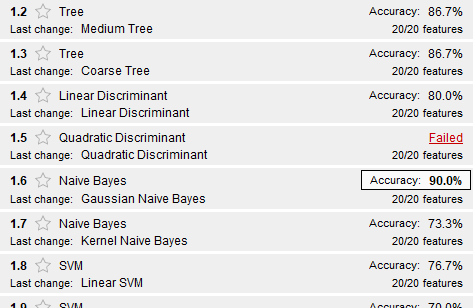

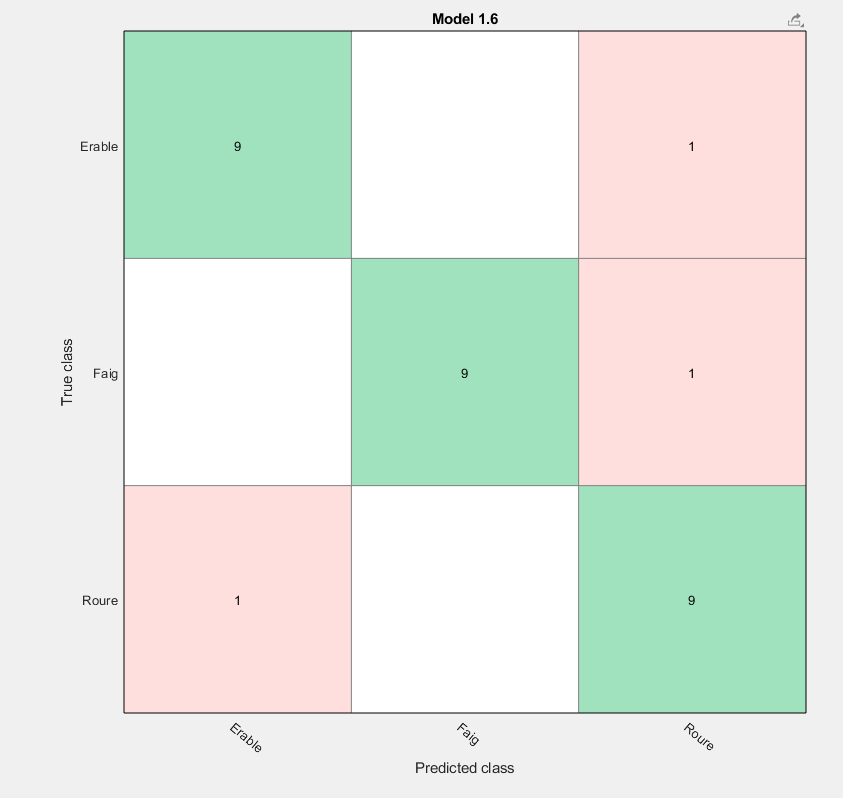

Haremos una prueba con los datos Test:

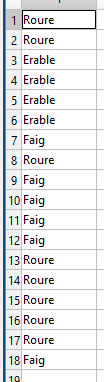

Como se puede observar y sabiendo los resultados correctos expuestos arriba, hay un gran porcentaje de fallos, un 20% aproximadamente. 

- Usando 20 descriptores nos da los siguientes resultados:

### Clasificación usando el módulo

- Usando 5 descriptores nos da los siguientes resultados:

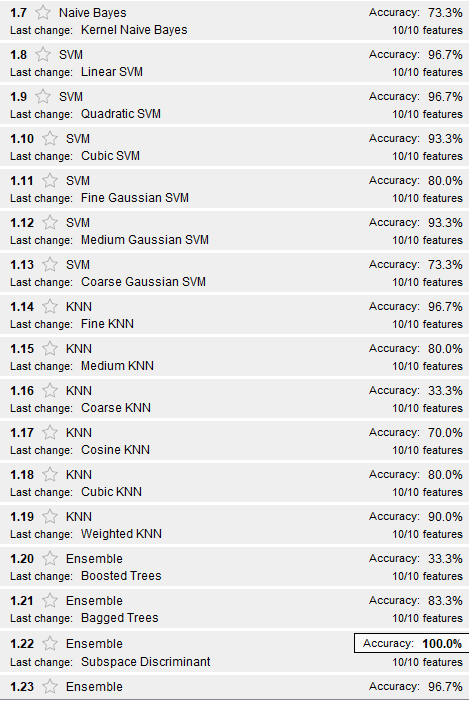

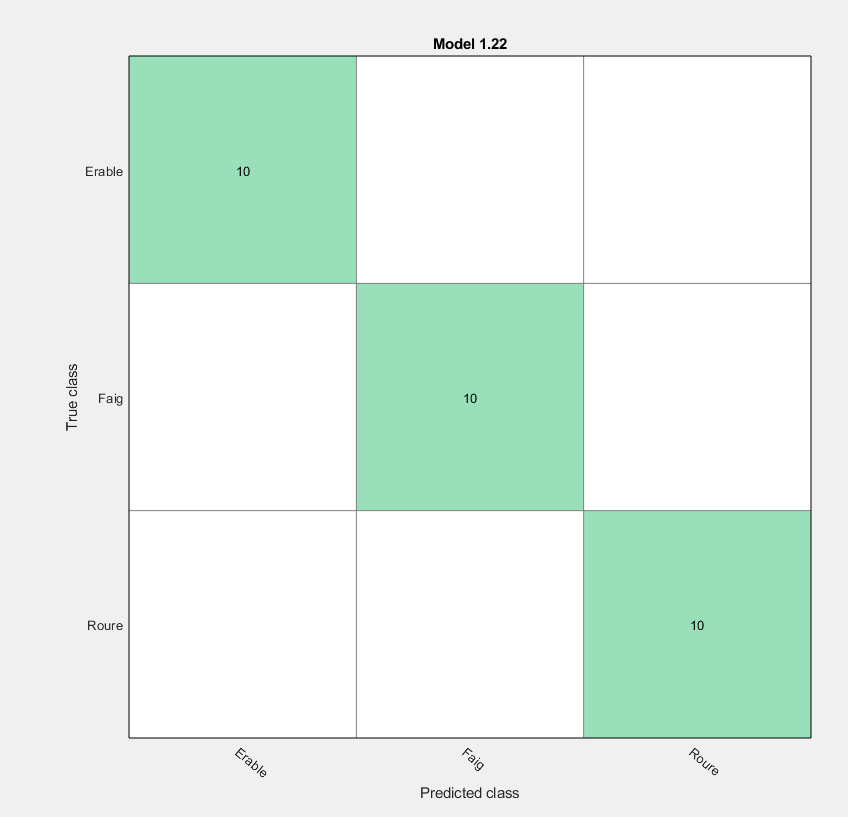

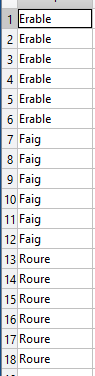

Buenos resultados aunque es posible debido a la poca cantidad de datos

- Usando 20 descriptores nos da los siguientes resultados:

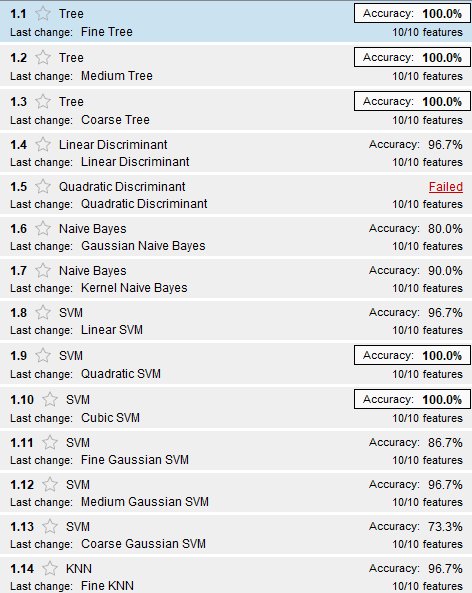

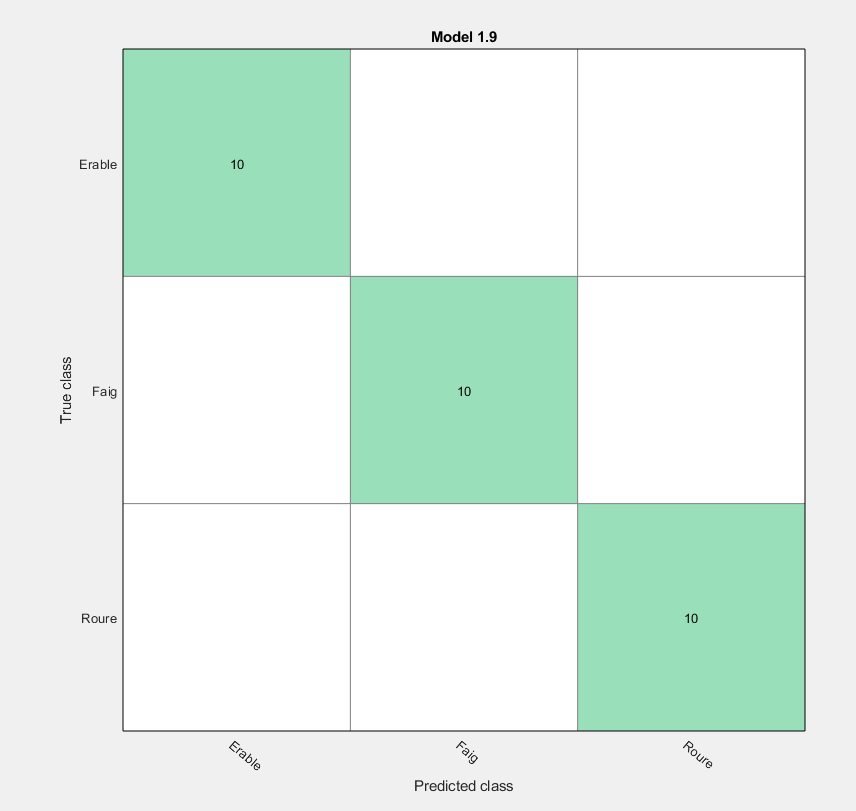

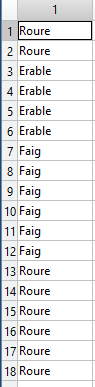

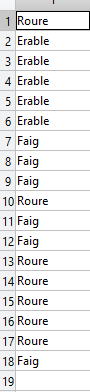

- Usando 50 descriptores nos da los siguientes resultados:

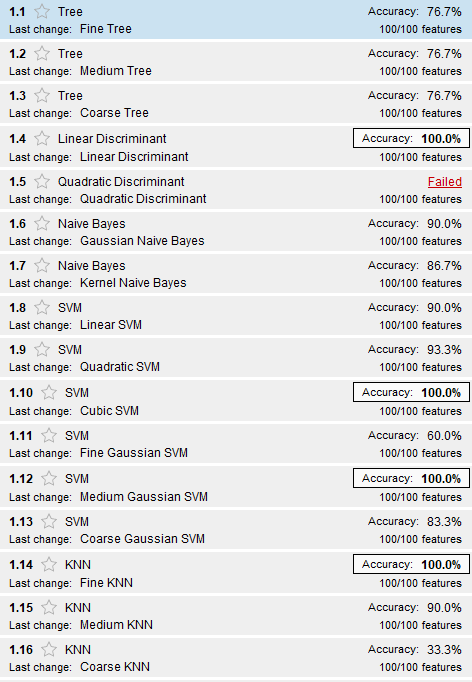

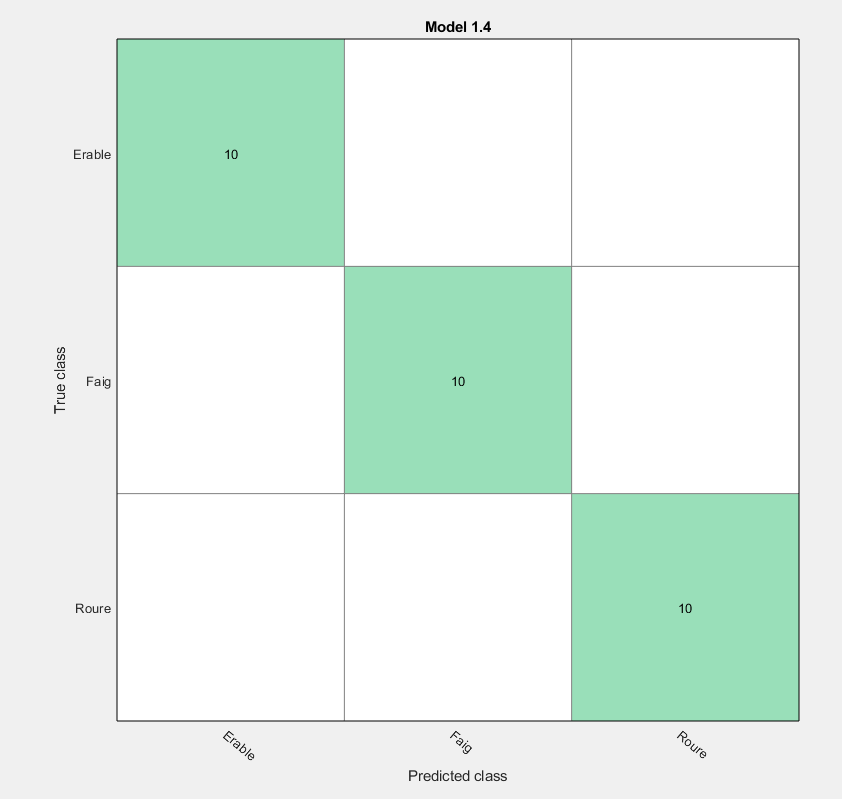

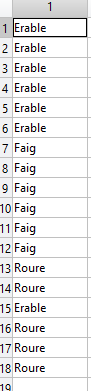

- Usando 75 descriptores nos da los siguientes resultados:

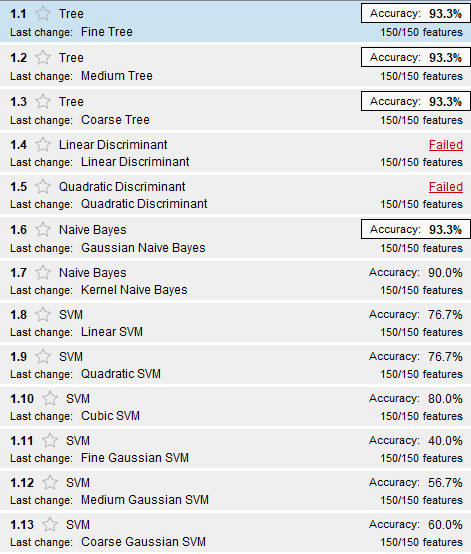

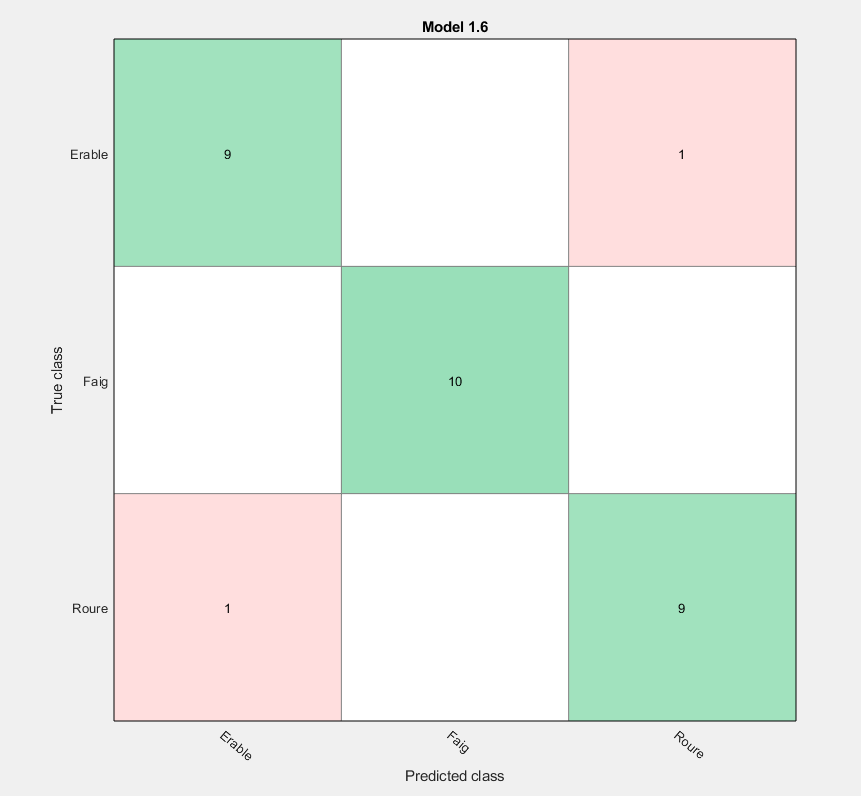

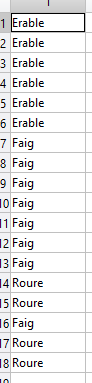

%im = imread('l2nr002.jpg')
%[descriptor] = descriptor_fourier(im,nan)
p = randperm(16);
train = p(1:10);
test = p(11:16);
[T1Train, T2Train, dataTrain] = getdataexercise2(train)

data =     3.6478    6.2503    6.0083    5.1783    6.1637    6.3466    5.4748    4.7473    5.3263    5.6686    4.4668    6.0896    5.2029    4.7913    4.3114    1.9668    4.6097    3.9461    4.3506    3.8756    2.7582    3.7474    4.4477    4.0024    4.3553    3.8544    3.1282    2.6696    2.5628    3.1039    3.5068    2.3938    1.5216    3.3274    2.3007    3.1716    2.7689    2.6222    2.6665    2.0677    3.3310    2.4306    2.5573    2.8257    2.0948    2.5964    2.6625    3.2450    1.2012    3.2343
    3.8152    6.8771    6.1727    5.9180    5.8778    6.2619    5.9195    5.6903    5.4097    5.8387    6.0505    5.7698    5.7766    5.6590    5.5498    5.3652    4.5658    4.5079    4.9129    4.7730    5.1080    4.3501    4.3370    4.3038    4.5207    4.4755    3.6776    4.7913    4.1122    3.8304    3.2717    3.8111    2.0494    2.8502    2.8851    3.5452    3.4741    3.3578    2.8259    3.4529    3.7576    2.4988    3.3837    2.6313    0.8121    2.6007    2.5795    2.7222    2.5899  

T1Train = 30×2 table
         Var1         namesleaf
    ______________    _________

    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Faig"   
    [1×300 double]    "Faig"   
    [1×300 double]    "Faig"   
    [1×300 double]    "Faig"   
    [1×300 double]    "Faig"   
    [1×300 double]    "Faig"   


T2Train = 30×2 table
         Var1         namesleaf
    ______________    _________

    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Faig"   
    [1×150 double]    "Faig"   
    [1×150 double]    "Faig"   
    [1×150 double]    "Faig"   
    [1×150 double]    "Faig"   
    [1×150 double]    "Faig"   


dataTrain =     3.6478    6.2503    6.0083    5.1783    6.1637    6.3466    5.4748    4.7473    5.3263    5.6686    4.4668    6.0896    5.2029    4.7913    4.3114    1.9668    4.6097    3.9461    4.3506    3.8756    2.7582    3.7474    4.4477    4.0024    4.3553    3.8544    3.1282    2.6696    2.5628    3.1039    3.5068    2.3938    1.5216    3.3274    2.3007    3.1716    2.7689    2.6222    2.6665    2.0677    3.3310    2.4306    2.5573    2.8257    2.0948    2.5964    2.6625    3.2450    1.2012    3.2343
    3.8152    6.8771    6.1727    5.9180    5.8778    6.2619    5.9195    5.6903    5.4097    5.8387    6.0505    5.7698    5.7766    5.6590    5.5498    5.3652    4.5658    4.5079    4.9129    4.7730    5.1080    4.3501    4.3370    4.3038    4.5207    4.4755    3.6776    4.7913    4.1122    3.8304    3.2717    3.8111    2.0494    2.8502    2.8851    3.5452    3.4741    3.3578    2.8259    3.4529    3.7576    2.4988    3.3837    2.6313    0.8121    2.6007    2.5795    2.7222    2.5

[T1Test, T2Test, dataTest] = getdataexercise2(test)

data =   -27.3319    6.7330    6.3030    5.7996    6.6231    6.4854    5.1848    5.8195    6.0239    5.8947    5.8535    5.9557    4.8443    5.5604    5.3926    4.5457    4.2850    5.1047    4.4114    4.5989    5.5281    4.1961    4.8110    4.2036    3.8491    3.4503    3.3772    3.3255    3.9148    3.3685    3.9698    4.2290    3.1905    2.9782    3.6097    2.7699    3.6029    3.4361    3.1489    2.2410    2.9764    3.0409    2.5951    2.9249    2.8180    3.4459    3.4113    2.2133    2.2726    1.6167
    4.2374    7.9803    7.6499    5.5623    7.1377    7.1419    6.4169    6.8696    6.5860    5.6211    6.5973    6.4397    6.2955    6.6250    6.5223    6.5752    6.2874    5.9071    5.4322    5.4483    5.7386    5.4288    5.7967    5.2433    5.2122    5.5470    5.3096    5.7215    5.3152    5.0391    4.9740    4.4029    5.5090    4.0987    4.2803    4.9877    4.8771    2.9257    5.2886    2.7607    3.0926    4.0234    3.3416    4.3075    4.2897    4.1524    3.1540    4.1946    4.2352  

T1Test = 18×2 table
         Var1         namesleaf
    ______________    _________

    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Erable" 
    [1×300 double]    "Faig"   
    [1×300 double]    "Faig"   
    [1×300 double]    "Faig"   
    [1×300 double]    "Faig"   
    [1×300 double]    "Faig"   
    [1×300 double]    "Faig"   
    [1×300 double]    "Roure"  
    [1×300 double]    "Roure"  
    [1×300 double]    "Roure"  
    [1×300 double]    "Roure"  


T2Test = 18×2 table
         Var1         namesleaf
    ______________    _________

    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Erable" 
    [1×150 double]    "Faig"   
    [1×150 double]    "Faig"   
    [1×150 double]    "Faig"   
    [1×150 double]    "Faig"   
    [1×150 double]    "Faig"   
    [1×150 double]    "Faig"   
    [1×150 double]    "Roure"  
    [1×150 double]    "Roure"  
    [1×150 double]    "Roure"  
    [1×150 double]    "Roure"  


dataTest =   -27.3319    6.7330    6.3030    5.7996    6.6231    6.4854    5.1848    5.8195    6.0239    5.8947    5.8535    5.9557    4.8443    5.5604    5.3926    4.5457    4.2850    5.1047    4.4114    4.5989    5.5281    4.1961    4.8110    4.2036    3.8491    3.4503    3.3772    3.3255    3.9148    3.3685    3.9698    4.2290    3.1905    2.9782    3.6097    2.7699    3.6029    3.4361    3.1489    2.2410    2.9764    3.0409    2.5951    2.9249    2.8180    3.4459    3.4113    2.2133    2.2726    1.6167
    4.2374    7.9803    7.6499    5.5623    7.1377    7.1419    6.4169    6.8696    6.5860    5.6211    6.5973    6.4397    6.2955    6.6250    6.5223    6.5752    6.2874    5.9071    5.4322    5.4483    5.7386    5.4288    5.7967    5.2433    5.2122    5.5470    5.3096    5.7215    5.3152    5.0391    4.9740    4.4029    5.5090    4.0987    4.2803    4.9877    4.8771    2.9257    5.2886    2.7607    3.0926    4.0234    3.3416    4.3075    4.2897    4.1524    3.1540    4.1946    4.23

%view(trainedModel.ClassificationTree,'Mode','graph');

yfit = trainedModel.predictFcn(T2Test);

function [T1, T2, data] = getdataexercise2(listaNum)
    nDesc = 75;
    descriptorsComp = [];
    descriptorsMod = [];
    namesleaf = [];
    images = ["l2nr0", "l15nr0", "l4nr0"];
    fulles = ["Erable", "Faig", "Roure"];
    for k = 1:length(images)
        image = images(k);
        for i = listaNum
            if i < 10
                im = imread(strcat(fulles(k),'/',image ,'0', int2str(i) ,'.jpg'));
            else
                im = imread(strcat(fulles(k),'/',image ,int2str(i) ,'.jpg'));
            end
            [descriptorComp,descriptorMod] = descriptor_fourier(im, nDesc);
            descriptorsComp = [descriptorsComp; descriptorComp];
            descriptorsMod = [descriptorsMod; descriptorMod];
            namesleaf = [namesleaf; fulles(k)];
        end
    end
    data = descriptorsMod
    T1 = table(double(descriptorsComp), namesleaf);
    T2 = table(double(descriptorsMod), namesleaf);
    writetable(T1,'resultado1.csv');
    writetable(T2,'resultado2.csv');
end


function [descriptorDiv,descriptor] = descriptor_fourier(im, Ndescriptors)
    [d1 d2 d3] = size(im);
    if (d3 == 3)
        im = rgb2gray(im);
    end
    im =im2bw(im, graythresh(im)); % Binarització per Otsu
    im = imcomplement(im);
    im=imresize(im,1/16);
    % obtenim el contorn
    ero=imerode(im,strel('disk',1));
    cont=xor(ero,im);
    % obtenim les coordenades del contorn
    [fila col] = find(im,1); % Busquem el primer píxel
    B = bwtraceboundary(im,[fila col],'E'); %direccio est a l'atzar
    % B conté les coordenades
    % centrem coordenades
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:); %dupliquem l'ultim
        mida=mida+1;
    end
    % Calculem la Fast Fourier Transform
    descriptor=fft(s);
    % Obtenim el 
    if (~isnan(Ndescriptors))
        descriptor = [descriptor(1:Ndescriptors);descriptor(end-Ndescriptors+1:end)];
        descriptorDiv = [real(descriptor); imag(descriptor)];
    end
    descriptor = log(abs(descriptor));
    descriptor = descriptor';
    descriptorDiv = descriptorDiv';
end